# Fet a classe 12/02/1998

## Un primer gràfic

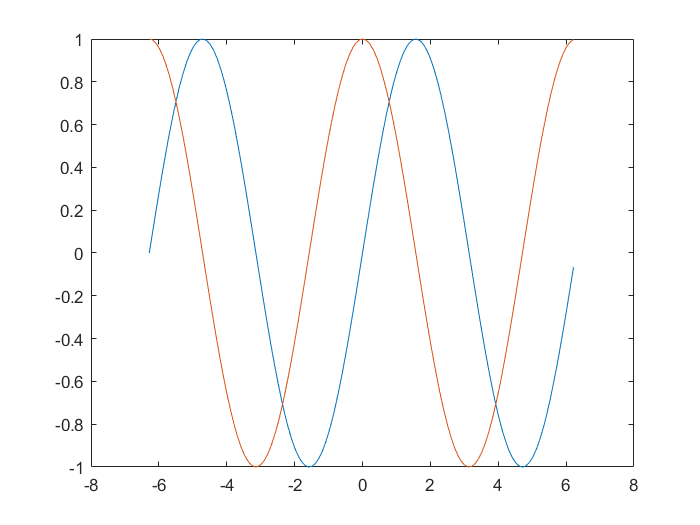

x=-2*pi:0.1:2*pi; %a:b:c generar de a->c incrementant de b en b
y=sin(x);
z=cos(x);
plot(x,y,x,z)

## Decoració gràfic

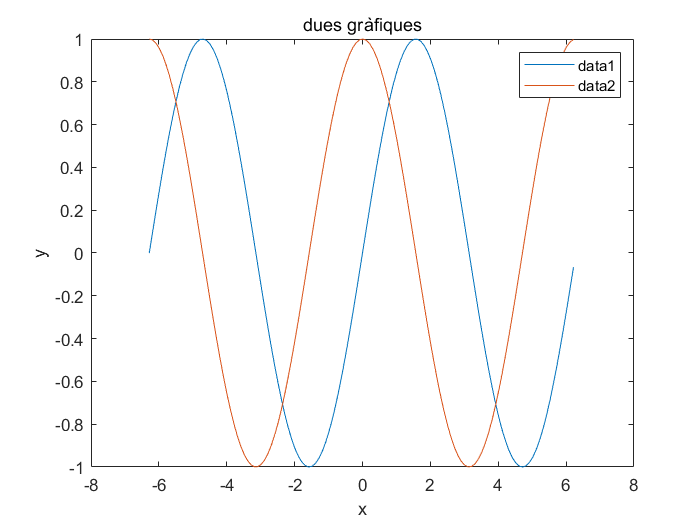

plot(x,y,x,z),title('dues gràfiques')
xlim([-8 8])
ylim([-1 1])
legend('show')
xlabel('x')
ylabel('y')

## Opeacions "vectorials"

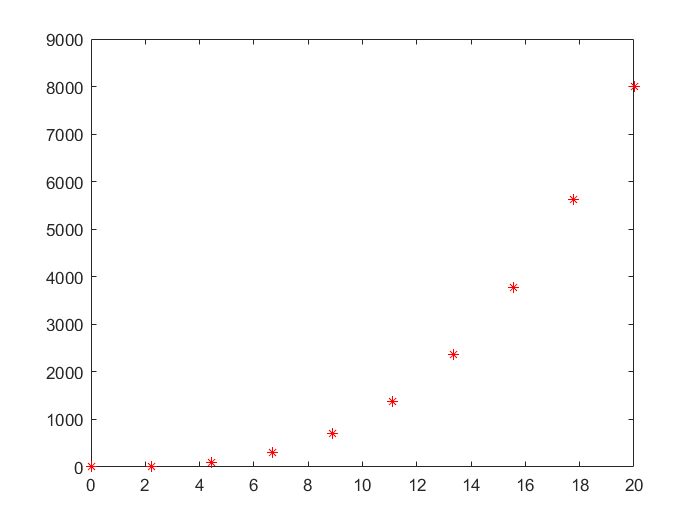

t=linspace(0,20,10);
plot(t,t.^3+1,'r*') %el punt "." serveix per aplicar l'operació als elemets

## Operacions amb "matrius"

A=ones(5)

A =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


B=magic(5)

B =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


A+B

ans =     18    25     2     9    16
    24     6     8    15    17
     5     7    14    21    23
    11    13    20    22     4
    12    19    26     3    10


A*B

ans =     65    65    65    65    65
    65    65    65    65    65
    65    65    65    65    65
    65    65    65    65    65
    65    65    65    65    65


A.*B

ans =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


C=2*ones(5);
B\C

ans =     0.0308    0.0308    0.0308    0.0308    0.0308
    0.0308    0.0308    0.0308    0.0308    0.0308
    0.0308    0.0308    0.0308    0.0308    0.0308
    0.0308    0.0308    0.0308    0.0308    0.0308
    0.0308    0.0308    0.0308    0.0308    0.0308


B/C

ans =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


## Funcions anònimes

f=@(t)t.^3+1

f = 包含以下值的 function_handle :
    @(t)t.^3+1


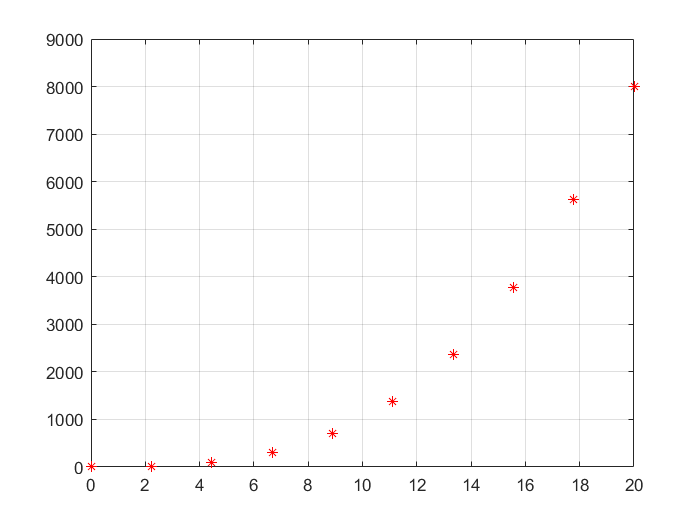

plot(t,f(t), '*r'),grid %* = punts en lloc de linea, r = red

## Funcions anònimes dos arguments

f=@(t,a)sin(a*t.^3+1)

f = 包含以下值的 function_handle :
    @(t,a)sin(a*t.^3+1)


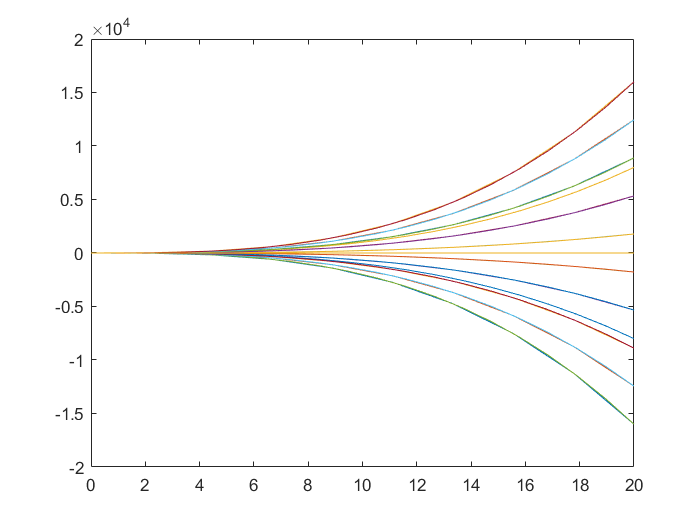

t=linspace(0,20,20);
a=linspace(-2,2,10);
hold on
for k=1:10 %bucle de 1 a 10
    plot(t,f(t,a(k))),grid 
end
hold off

## Exemple us de handle

g=@(t)f(t,1)

g = 包含以下值的 function_handle :
    @(t)f(t,1)


integral(g,0,20)

ans = 0.8927